# Tarea 1

# Control Robusto y Análisis  de Desempeño  : Vehículo Aereo no Tripulado. 

## Dylan Ortiz Mayorga

## Juan Pablo Vallejo Montañez

### Universidad Nacional de Colombia 

#### **1.Consideraciónes Inciales**

clc 
clear
load("modelo_lin.mat");

El objetivo es diseñar controladores PID y Hinf para una planta correspondiente a una aeronave tipo UAV. Se parte de un modelo nominal  lineal acoplado.

Para cada uno de los ejes del UAV se tiene la siguiente nomenclatura


$$$$


K=-10

K =    -10


**Eje Longitudinal**

%Nomnclatura variables Eje Longitudinal 
% Inputs (1) Elevator, (2) Throttle
% Outputs (3) q-velocidad pitch ,(4) theta-angulo pitch
Gel_pit=tf(longmod(4,1))

Gel_pit =
 
  From input "elevator" to output "theta":
          -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



Gel_q=tf(longmod(3,1))

Gel_q =
 
  From input "elevator" to output "q":
  -134.1 s^5 - 1869 s^4 - 6807 s^3 - 2268 s^2 - 0.07966 s - 1.917e-17
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



[numt ,dent]=tfdata(Gel_pit)

numt = 1×1 cell array
    {[0 0 -1.340659144516756e+02 -1.869134594234483e+03 -6.806905591459379e+03 -2.267938356990971e+03 -0.079657691930210]}


dent = 1×1 cell array
    {[1 29.947500867347571 3.928712088663158e+02 1.609065046390366e+03 6.376874663928061e+02 6.419869018493118e+02 0.077262133080403]}


numt1=cell2mat(numt)

numt1 = 1.0e+03 *

                   0                   0  -0.134065914451676  -1.869134594234483  -6.806905591459379  -2.267938356990971  -0.000079657691930


dent1=cell2mat(dent)

dent1 = 1.0e+03 *

   0.001000000000000   0.029947500867348   0.392871208866316   1.609065046390366   0.637687466392806   0.641986901849312   0.000077262133080


[numq , denq]=tfdata(Gel_q)

numq = 1×1 cell array
    {[0 -1.340661129348525e+02 -1.869137361468601e+03 -6.806915669011549e+03 -2.267941714649863e+03 -0.079657809863511 -1.917460306924082e-17]}


denq = 1×1 cell array
    {[1 29.947500867347539 3.928712088663151e+02 1.609065046390363e+03 6.376874663928025e+02 6.419869018493134e+02 0.077262133080396]}


numq1=cell2mat(numq)

numq1 = 1.0e+03 *

                   0  -0.134066112934852  -1.869137361468601  -6.806915669011548  -2.267941714649863  -0.000079657809864  -0.000000000000000


denq1=cell2mat(denq)

denq1 = 1.0e+03 *

   0.001000000000000   0.029947500867348   0.392871208866315   1.609065046390364   0.637687466392802   0.641986901849313   0.000077262133080


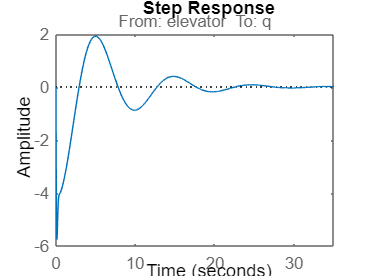

step(Gel_q)

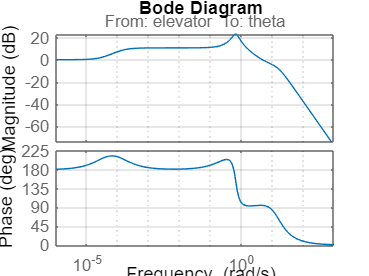

bode(Gel_pit)
grid on

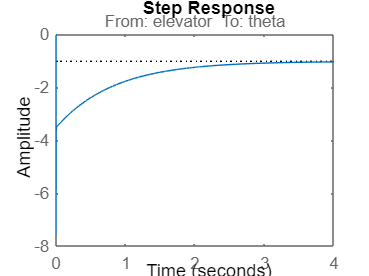

step(Gel_pit)

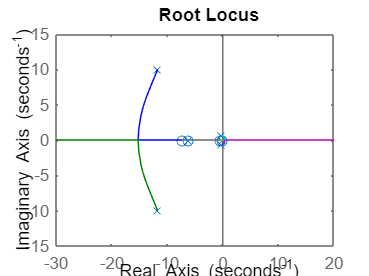

rlocus(Gel_pit)

% % z1=zero(Gel_pit)
p1=pole(Gel_pit)

p1 = -11.714141744174153 +10.024952110138994i
-11.714141744174153 -10.024952110138994i
 -6.199724261954605 + 0.000000000000000i
 -0.159686377100901 + 0.640349097646646i
 -0.159686377100901 - 0.640349097646646i
 -0.000120362842866 + 0.000000000000000i


Hel_pit=feedback(Gel_pit,K)

Hel_pit =
 
  From input "elevator" to output "theta":
               -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  -----------------------------------------------------------------------------
  s^6 + 29.95 s^5 + 1734 s^4 + 2.03e04 s^3 + 6.871e04 s^2 + 2.332e04 s + 0.8738
 
Continuous-time transfer function.



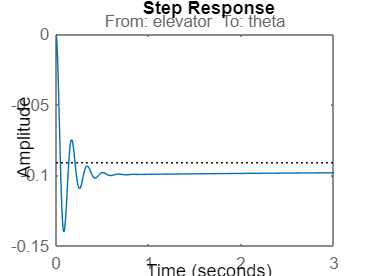

step(Hel_pit)

Eje lateral 

x2=-2;
x1=-3;
a=1;
k1=a*(-x2)/((x2-x1)*x1*x2)

k1 =    0.333333333333333


k2=-a*(-x1)/((x2-x1)*x1*x2)

k2 =   -0.500000000000000


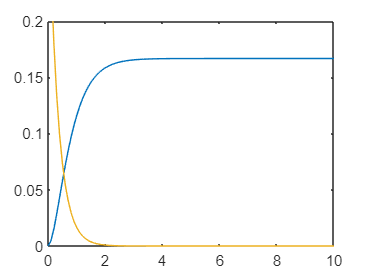

t=linspace(0,10,100);
unitstep=t>=0;
z=k1*exp(x1*t);
y=k2*exp(x2*t);
x=(a/(x1*x2))*unitstep+y+z;


plot(t,x,t,y,t,z)
ylim([0 0.2])

Prueba Raices polinomio 

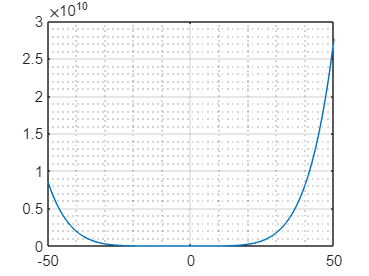

format long 
s=linspace(-50,50,1000);
    fun=s.^6+29.95*s.^5+392.9*s.^4+1609*s.^3+637.7*s.^2+642*s+0.07726;
    plot(s,fun)
    grid on, grid minor 

    numer=[-134.1,-1869,-6807,-2268,-0.07966,-1.917];
    denomin=[1,29.95,392.9,1609,637.7,642,0.07726]

denomin = 1.0e+03 *

   0.001000000000000   0.029950000000000   0.392900000000000   1.609000000000000   0.637700000000000   0.642000000000000   0.000077260000000


    div=[0.001  0]

div = 1.0e-03 *

   1.000000000000000                   0


    xd=deconv(denomin,div)

xd = 1.0e+06 *

   0.001000000000000   0.029950000000000   0.392900000000000   1.609000000000000   0.637700000000000   0.642000000000000


    xd2=deconv(xd,div)

xd2 = 1.0e+09 *

   0.001000000000000   0.029950000000000   0.392900000000000   1.609000000000000   0.637700000000000


    denq2=[denq1,0]

denq2 = 1.0e+03 *

   0.001000000000000   0.029947500867348   0.392871208866315   1.609065046390364   0.637687466392802   0.641986901849313   0.000077262133080                   0


    [r,p,l]=residue(numer,denomin)

r = -66.948292843592071 -28.743942153717295i
-66.948292843592071 +28.743942153717299i
 -0.066899856397975 + 0.000000000000000i
 -0.066763862539988 - 1.441089046074451i
 -0.066763862539988 + 1.441089046074451i
 -0.002986731337872 + 0.000000000000000i


p = -11.715980299433648 +10.024435103201574i
-11.715980299433648 -10.024435103201574i
 -6.198537154843952 + 0.000000000000000i
 -0.159690944612599 + 0.640373229798189i
 -0.159690944612599 - 0.640373229798189i
 -0.000120357063558 + 0.000000000000000i



l =

     []



    %polo1
    %pol1=[1 -p(7)];
    %enq3=deconv(denq2,pol1)



%w=linspace(0,1000,10000);
%u1=r(7)*exp(p(7)*w);
%u2=r(6)*exp(p(6)*w);
%u3=r(5)*r(4)*exp(real(p(5))*t);
%fin=u1+u2;
%plot(w,fin,w,u1,w,u2)



t1=linspace(0,12,100);
nuk=[1];
demo=[1 2 4]

demo =      1     2     4


de=[1 1 4 0];
G=tf(nuk,demo);
[a,b,c]=residue(nuk,de)

a =  -0.125000000000000 + 0.032274861218395i
 -0.125000000000000 - 0.032274861218395i
  0.250000000000000 + 0.000000000000000i


b =  -0.500000000000000 + 1.936491673103708i
 -0.500000000000000 - 1.936491673103708i
  0.000000000000000 + 0.000000000000000i



c =

     []



const=2*(real(a(1))*real(b(1))+imag(a(1))*imag(b(1)))

const =    0.250000000000000


fun1=a(3)*exp(real(b(3))*t1);
fun2=const*exp(real(b(2))*t1).*(-(1/sqrt(15))*sin(imag(b(1))*t1)-cos(imag(b(1))*t1));
fun3=fun1+fun2;

min=imag(a(1))

min =    0.032274861218395


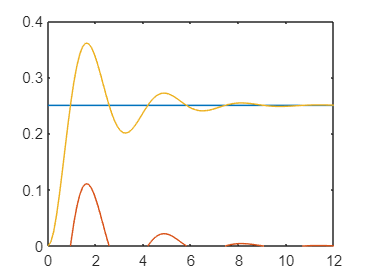


plot(t1,fun1,t1,fun2,t1,fun3)
ylim([0 0.4])
xlim([0 12])

pole(G)

ans =  -1.000000000000000 + 1.732050807568877i
 -1.000000000000000 - 1.732050807568877i


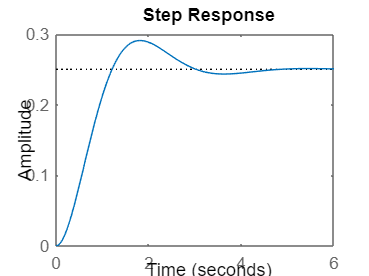

step(G);

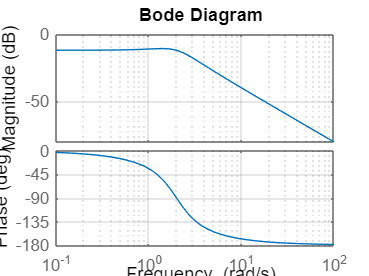

bode(G)
grid on


kmin=dent1

kmin = 1.0e+03 *

   0.001000000000000   0.029947500867348   0.392871208866316   1.609065046390366   0.637687466392806   0.641986901849312   0.000077262133080



numsis=[2*real(r(4)) 2*(imag(p(4))*imag(r(5))-real(r(4))*real(p(4)))]

numsis =   -0.133527725079976   1.824346525172982


densis=[1 -2*real(p(4)) real(p(4))^2+imag(p(4))^2]

densis =    1.000000000000000   0.319381889225199   0.435579071233428


sys=tf(numsis,densis)

sys =
 
     -0.1335 s + 1.824
  -----------------------
  s^2 + 0.3194 s + 0.4356
 
Continuous-time transfer function.



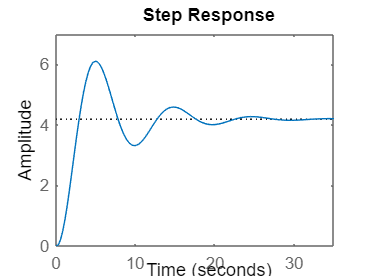

step(sys)

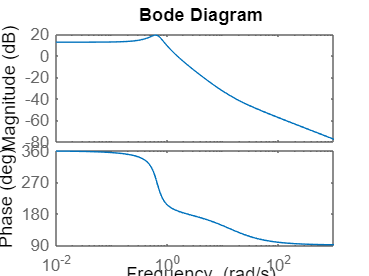

bode(sys)

pole(sys)

ans =  -0.159690944612599 + 0.640373229798189i
 -0.159690944612599 - 0.640373229798189i
